-  Wilson

A = [10,7,8,7; 7,5,6,5; 8,6,10,9; 7,5,9,10];
B = [32; 23; 33; 31];
X = A\B;

fprintf("Matricea A:");

Matricea A:

disp(A);

    10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10



fprintf("Matricea B:")

Matricea B:

disp(B);

    32
    23
    33
    31




Bp = [32.1;22.9;33.1;30.9];
fprintf("Matricea B perturbata:");

Matricea B perturbata:

disp(Bp);

   32.1000
   22.9000
   33.1000
   30.9000




Ap = [10,7,8.1,7.2;7.08,5.04,6,5;8,5.98,9.89,9;6.99,4.99,9,9.98];
fprintf("Matricea A perturbata:");

Matricea A perturbata:

disp(Ap);

   10.0000    7.0000    8.1000    7.2000
    7.0800    5.0400    6.0000    5.0000
    8.0000    5.9800    9.8900    9.0000
    6.9900    4.9900    9.0000    9.9800




% a) perturbam membrul drept
xp1 = A\Bp; % radacinile se schimba total la perturbarea membrului drept
eri1 = norm(Bp-B)/norm(B); % eroarea la intrare
ero1 = norm(xp1-X)/norm(X); % eroarea la iesire

raport1 = ero1/eri1; % raportul
fprintf("Eroarea pentru membrul drept %f", raport1);

Eroarea pentru membrul drept 2460.567236


% b) perturbam matricea
xp2 = Ap\B; % radacinile se schimba total la perturbarea matricii sist
eri2 = norm(A-Ap)/norm(A); % eroarea la intrare
ero2 = norm(X-xp2)/norm(X); % eroarea la iesire

raport2 = eri2/ero2; % raportul
fprintf("Eroarea pentru membrul stang %f", raport2);

Eroarea pentru membrul stang 0.000093

- Sa se studieze conditionarea matricei Hilbert in raport cu norma euclidiana n = 10..15

start = 10;
stop = 15;
matrix = zeros(1, stop-start); % vector de zerouri

for i = start:stop
    H = hilb(i);    % matricea Hilbert H(i,j) = 1/(i + j – 1)
    matrix(i-start+1) = cond(H, 2); % numarul de conditionare
end

fprintf("Hilbert");

Hilbert

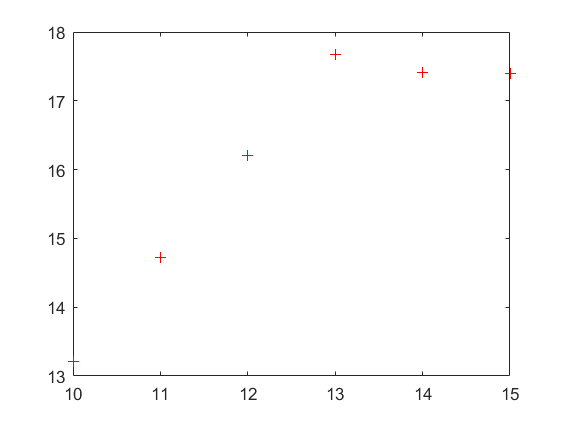

plot(start:stop, log10(matrix),'r+');

2.  Sa se studieze conditionarea matricei Vandermonde

% a) tk = -1+k*2/n (puncte echidistante in [-1,1]) 
% si n = 10; 15 in raport cu norma Cebsev.

warning("off");

start = 10;
stop = 15;

% initializam vectori de zerouri
matrix_a = zeros(1, stop-start);
matrix_b = zeros(1, stop-start);

for n = start:stop
    k = linspace(-1,1,n); % generam un vector cu n valori intre -1 si 1, diferenta: (x2-x1)/(n-1)
    t = -1 + 2 .* (k./n); % construim termenul
    V = vander(t); % construim matricea Vandermode
    matrix_a(n-start+1) = cond(V, inf); % conditionare in functie de norma Cebisev
end

% b) tk = 1/k; k = 1..n si n = 10; 15 in raport cu norma Cebsev.

for n = start:stop
    k = 1:n;
    o = ones(1, n); % generam un vector de 1
    t = o./k;   % construim termenul
    v = vander(t);  % construim matricea Vandermode
    matrix_b(n-start+1) = cond(v, inf); % conditionare in functie de norma Cebisev
end

fprintf("Vander");

Vander

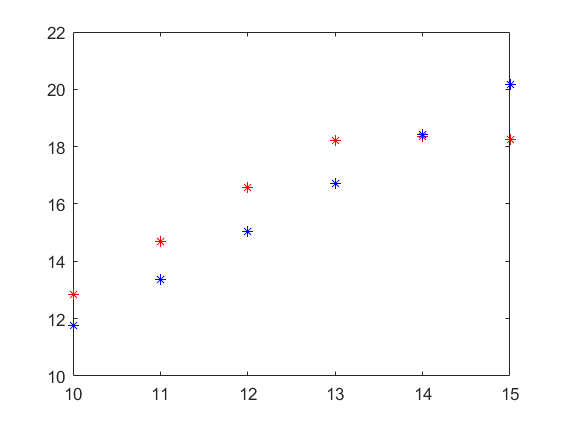

figure(1)
plot(start:stop, log10(matrix_a),'r*',start:stop, log10(matrix_b),'b*')

3. Sa se studieze teoretic si experimental conditionarea problemei determinarii radacinilor ecuatiei polinomiale cunoscandu-se coefcientii.

% Studiem conditionarea pentru (x-1)(x-2)...(x-n) = 0
r = [1:20]; % radacinile 
poli1 = poly(r); % polinomul
condpol(poli1, r)

ans = 	1.0e+13 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0069    0.0392    0.1682    0.5557    1.4194    2.8523    4.4307    5.4010    5.0243    3.5438    1.8121    0.6380    0.1378    0.0138


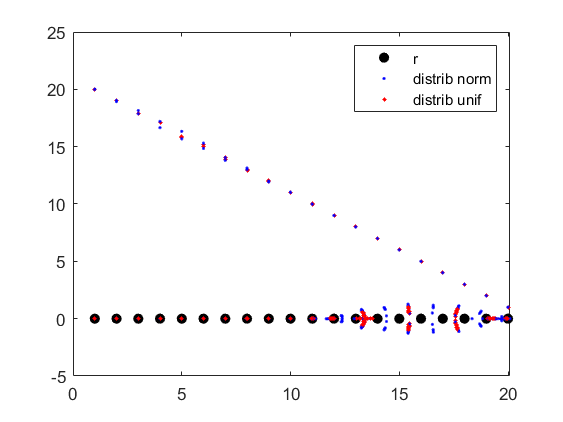


figure(1)
nn = length(r);
h = plot(r, zeros(1, nn), 'k.');
set(h,'Markersize', 21);
hold on

% perturbatii 
for i = 1:20
    % distributie normala
    poli1_per_norm = poli1 + normrnd(0, 1e-10, 1, length(poli1));   % perturbam polinomul initial
    r_norm = roots(poli1_per_norm); % calculam radacinile
    h2 = plot(r_norm,'b.');
    hold on
    set(h2,'Markersize',4)
    
    % distributie uniforma
    poli1_per_unif = poli1 + unifrnd(0, 1e-10, 1, length(poli1));
    r_unif = roots(poli1_per_unif);
    
    h3=plot(r_unif,'r*');
    hold on
    set(h3,'Markersize',2)
end
legend('r', 'distrib norm', 'distrib unif');
hold off


% Studiem conditionarea pentru a^k = 2^-k
poli2 = 2.^-(1:20);
condpol(poli2)

ans =     0.2972
    0.2972
    0.5871
    0.5871
    0.8626
    0.8626
    1.1168
    1.1168
    1.9000
    1.8766


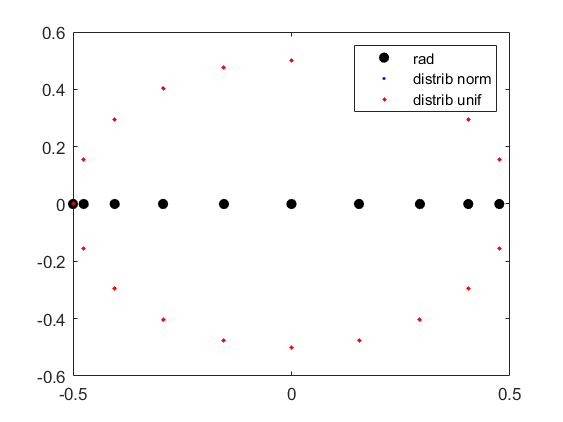

r2 = roots(poli2);

figure(2)
nn = length(r2);
h = plot(r2,zeros(1,nn),'k.');
set(h,'Markersize',21);
hold on

for i=1:20
    % distributie normala
    poli1_per_norm = poli2 + normrnd(0, 1e-10, 1, length(poli2));
    r_norm = roots(poli1_per_norm);
    h2=plot(r_norm,'b.');
    hold on
    set(h2,'Markersize',4)
    
    % distributie uniforma
    poli1_per_unif = poli2 + unifrnd(0, 1e-10, 1, length(poli2));
    r_unif = roots(poli1_per_unif);
    h3=plot(r_unif,'r*');
    hold on
    set(h3,'Markersize',2)
end
legend('rad', 'distrib norm', 'distrib unif');
hold off


% Concluzie: Pentru acest caz, punctele din cele 2 distributii sunt destul
% de apropiate